# quick script to make a symbolic von Karman turbulence spectrum (as per NASTRAN TABRNDG)

lengthScale = 24.0807;
flightSpeed = 25.7155;

p = 1/3;
k = 1.339;

Tchar = lengthScale/flightSpeed;
% syms Tchar
syms angularFreqs f real

numer = 1 + 2*(p+1)*k^2*Tchar^2*angularFreqs^2;
denom = (1 + k^2*Tchar^2*angularFreqs^2)^(p + 3/2);

psdf = 2*Tchar*numer/denom

$$psdf = \frac{\frac{9953638211091345604363123883235\,{\mathrm{angularFreqs}}^{2}}{1267650600228229401496703205376}+\frac{2108647149517231}{1125899906842624}}{{\left(\frac{1770146479942757\,{\mathrm{angularFreqs}}^{2}}{1125899906842624}+1\right)}^{11/6}}$$

psdf_f = subs(psdf, angularFreqs, 2*pi*f)

$$psdf\_f = \frac{\frac{9953638211091345604363123883235\,\pi^{2}\,f^{2}}{316912650057057350374175801344}+\frac{2108647149517231}{1125899906842624}}{{\left(\frac{1770146479942757\,\pi^{2}\,f^{2}}{281474976710656}+1\right)}^{11/6}}$$

## What's the integral?

I = int(psdf_f,f,0,Inf)

$$I = \frac{37326143291592546543523501941439\,\sqrt{5310439439828271}\,\sqrt{\pi }}{3154202400428480605653813837805167575040\,\Gamma (\frac{2}{3})\,\Gamma (\frac{5}{6})}$$

eval(I)

ans = 1.0000


vpaintegral(psdf_f,f,0,Inf)

$$ans = 0.999989$$

## plotty plot

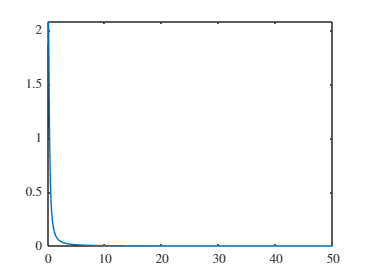

fplot(psdf_f,[0 50])